# Assignment 1 in ModSim

#### By Alexander Brevad Rambech

### Task 1

**a)** 

    1. This is already on state-space form

    2. The state-space representation of $\ddot{x} + c\dot{x} + g(1-(\frac{x_d}{x})^K)$ is

        
$$x_1 = x$$


        
$$x_2 = \dot{x}_1 = \dot{x}$$


        
$$\dot{x}_2 = \ddot{x} = -cx_2 - g(1-(\frac{x_d}{x_1})^K)$$


    3. This is already on state-space form

**b)**

    1. 

### Task 2

**a)**

%Init
clear; clc;

t0 = 0;
tend = 5;

x0 = [1, 0];

% ODE (5)
[t1, x1] = ode45(@(t1, x1) square(x1), [t0 tend], x0(1));


% ODE(6)
[t2, x2] = ode45(@(t2, x2) root(x2), [t0 tend], x0(2));

% functions found at the on the last page

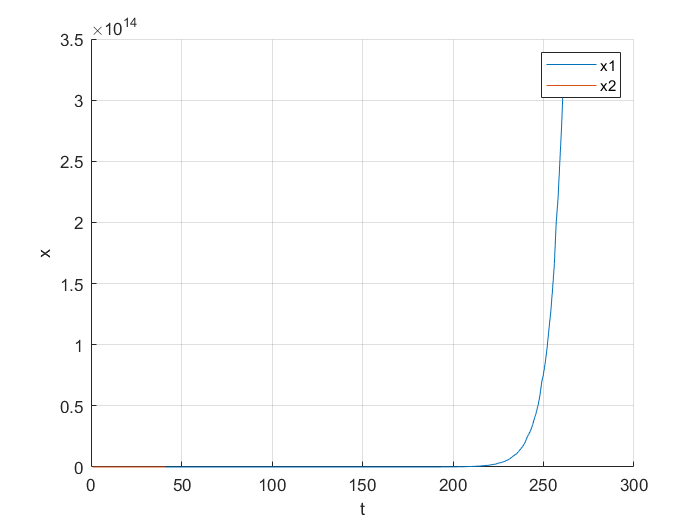

% Plot
figure(1); clf; hold on; grid on;
plot(x1, 'displayname', 'x1');
plot(x2, 'displayname', 'x2');
legend();
xlabel('t');
ylabel('x');

For the first ODE we see get a failure when the function grows large. The second ODE seems to stay at zero.

**b)**

The solution of the first ODE is only locally Lipschitz, because it is unbounded after a certain point. This is also pointed out by the MATLAB compiler as the function grows outside the integration tolerances. 

The solution of the second initial value problem is the trivial solution, because $\sqrt{|0|} =0 $.

### Task 3

**a)**

     Using the rules provided I found the following four governing equations:

        
$$\dot{H} = (b - d)H + H^2b_d-HiZ
$$


        
$$\dot{Z} = Dr - HnZ + Ia$$


        
$$\dot{I} = HiZ - (d + a)I$$


        
$$D = Id + HnZ - Dr + Hd$$


    This check out when we look at the hint: $\dot{H} + \dot{Z} + \dot{I} + \dot{D}= bH - H^2b_d$

**b)**

    The new governing equations are given by:

        
$$\dot{H} = (b - d)H + H^2b_d-HiZ$$


        
$$\dot{Z} = Dr - HnZ + Ia - Zq_z$$


        
$$\dot{I} = HiZ - (d + a + q_i)I$$


        
$$D = Id + HnZ - Dr + Hd + Qd_q$$


        
$$Q = Iq_i + Zq_z - Qd_q$$


**c)**

clear; clc;
% Init
% a(1), b(2), b_d(3), d(4), i(5), n(6), r(7), q_i(8), q_z(9), d_q(10)
params = [1.4*10^(-6), 3.1*10^(-8), 5.6*10^(-16), 2.8*10^(-8), 2.6*10^(-6), 1.4*10^(-6), 2.8*10^(-7), 2.7*10^(-6), 2.7*10^(-6), 2.8*10^(-5)];

init_cond = [(params(2)-params(4))/params(3), 0, 0, 0, 0];
t0 = 0;
tf = 100*24*3600;
%times = t0:1000:tf;
tid = linspace(t0, tf, 100)

tid = 	1.0e+06 *

         0    0.0873    0.1745    0.2618    0.3491    0.4364    0.5236    0.6109    0.6982    0.7855    0.8727    0.9600    1.0473    1.1345    1.2218    1.3091    1.3964    1.4836    1.5709    1.6582    1.7455    1.8327    1.9200    2.0073    2.0945    2.1818    2.2691    2.3564    2.4436    2.5309    2.6182    2.7055    2.7927    2.8800    2.9673    3.0545    3.1418    3.2291    3.3164    3.4036    3.4909    3.5782    3.6655    3.7527    3.8400    3.9273    4.0145    4.1018    4.1891    4.2764


% ODE options
init_step = 24*3600;
opts = odeset('AbsTol', 1, 'RelTol', 1e-8, 'InitialStep', init_step);

% Run ODE
[t1, x1] = ode45(@(t, x) Lokta_Q(x, params), tid, init_cond);

% x = [H(1), Z(2), I(3), D(4), Q(5)]
 

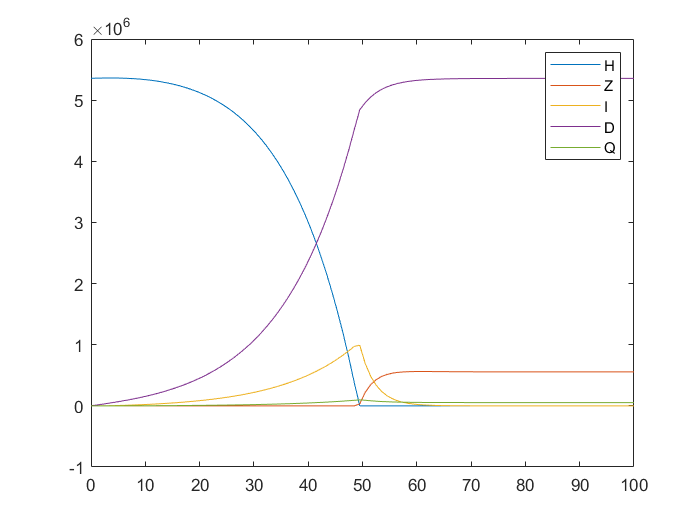

% Plot 
figure(3);
plot(t1/(24*3600), x1);
legend('H', 'Z', 'I', 'D', 'Q');

% Functions

% ODE (5)

function dx = square(x)
    dx = x^2;
end

% ODE (6)
function dx = root(x)
     dx = sqrt(abs(x));
end

% sys
function dx = Lokta_Q(x, params)
    dH = (params(2)-params(4))*x(1) + x(1)^2*params(3) - x(1)*params(5)*x(2);
    dZ = x(4)*params(7) - x(1)*params(6)*x(2) + x(3)*params(1) - x(2)*params(9);
    dI = x(1)*params(5)*x(2) - (params(1) + params(8) + params(4))*x(3);
    dD = x(3)*params(4) + x(1)*params(6)*x(2) - x(4)*params(7) + x(1)*params(4) + x(5)*params(10);
    dQ = x(3)*params(8) + x(2)*params(9) - x(5)*params(10);
    
    dx = [dH; dZ; dI; dD; dQ];
end
